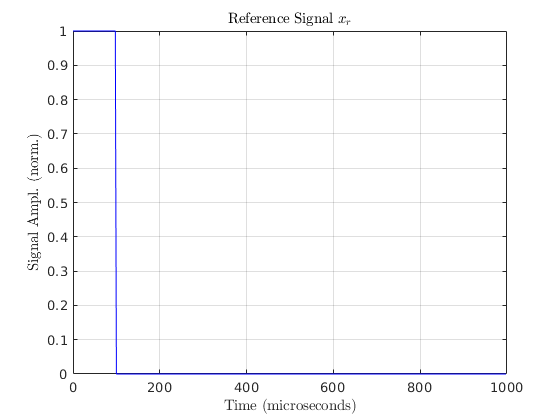

set(0,'defaultTextInterpreter','latex');

T = 1e-3;
t0 = 0;
t1 = 0.6*T;
Fs = 400e3;
rect = phased.RectangularWaveform("SampleRate",Fs,"DurationSpecification","Pulse width","PulseWidth",0.1*T,"PRF",1/T,"OutputFormat","Samples","NumSamples",T*Fs);
t = 0:1/Fs:T-1/Fs;
x0 = rect()';
x0 = abs(x0);

k = physconst("Boltzmann");
bw = 2*Fs;
P_n = db(T*Fs,'power');

x1 = circshift(x0,floor(t1*Fs));
x1 = abs(x1+wgn(1,size(x1,2),-P_n,1,20210113,"dBW"));

[ambmag, delay] = ambgfun(x0,x1,Fs,[rect.PRF rect.PRF],"Cut","Doppler");
ambmag1 = ambgfun(x1,x1,Fs,[rect.PRF rect.PRF]);
figure;
surfc(ambmag1,"EdgeColor","none");
view([-0.000 0.600]);
figure;
plot(t*1e6,normalize(x0,"range"),'b');
xlabel("Time (microseconds)");
ylabel("Signal Ampl. (norm.)");
title("Reference Signal $x_r$");
grid on;
print -depsc reference_signal.eps

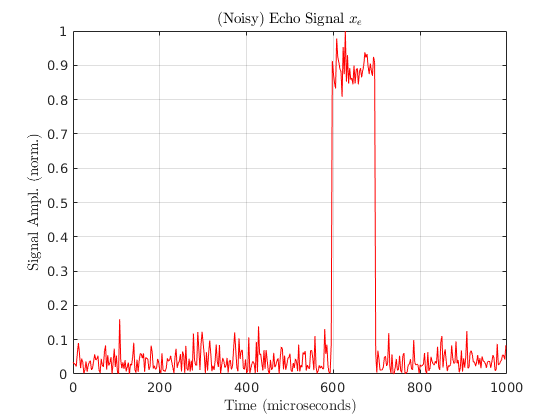

figure;
plot(t*1e6,normalize(x1,"range"),'r');
xlabel("Time (microseconds)");
ylabel("Signal Ampl. (norm.)");
title("(Noisy) Echo Signal $x_e$");
grid on;
print -depsc echo_signal.eps

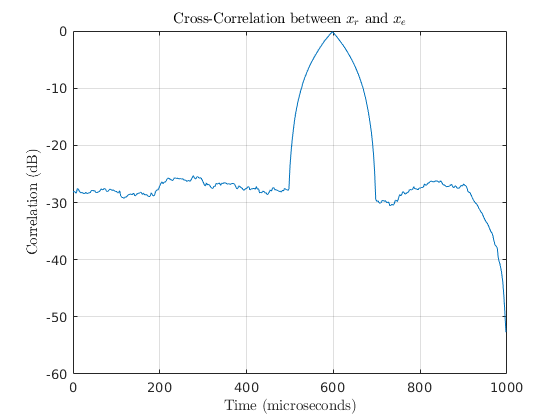

figure;
plot(delay(ceil(end/2):end)*1e6,db(ambmag(ceil(end/2):end)));
xlabel("Time (microseconds)");
ylabel("Correlation (dB)");
title("Cross-Correlation between $x_r$ and $x_e$");
grid on;
print -depsc correlation_db.eps

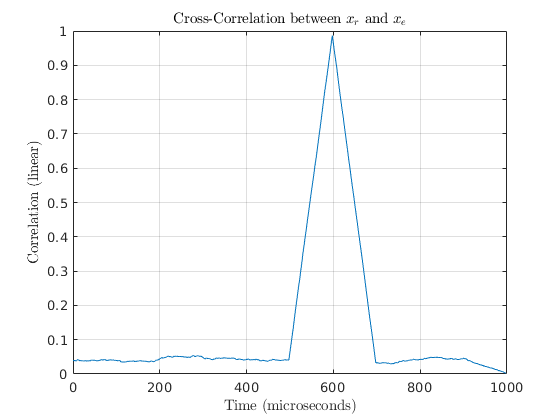

figure;
plot(delay(ceil(end/2):end)*1e6,ambmag(ceil(end/2):end));
xlabel("Time (microseconds)");
ylabel("Correlation (linear)");
title("Cross-Correlation between $x_r$ and $x_e$");
grid on;
print -depsc correlation_linear.eps